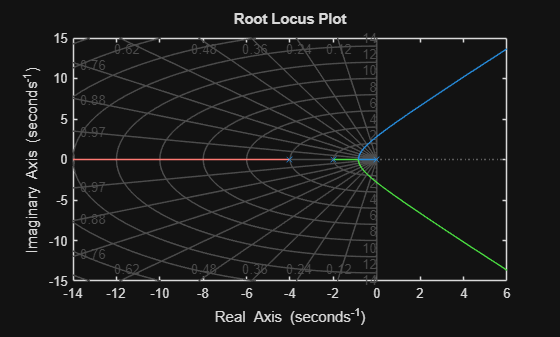

clc
clear
close all

% Transfer Function
num = [1];
den = conv([1 0],conv([1 2],[1 4]));

sys = tf(num,den);

% Root Locus
figure
rlocus(sys)
title('Root Locus Plot')
grid on

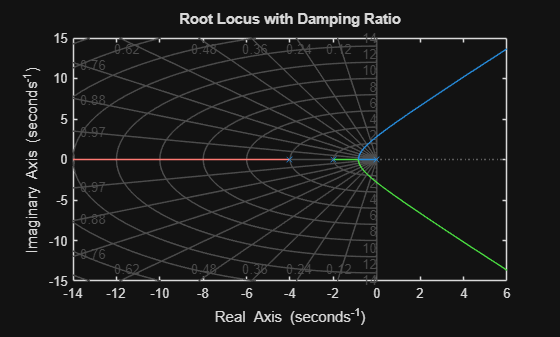

Select a point in the graphics window


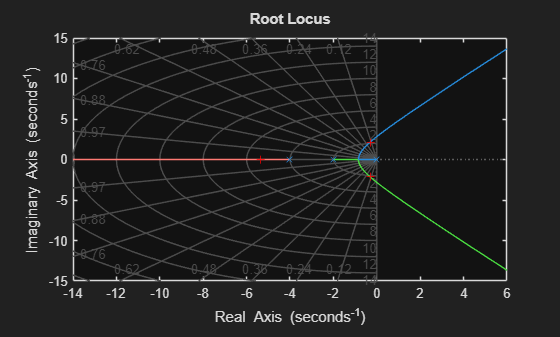

selected_point = -2.2258 - 2.4691i

k = 25.0605

p =   -5.3789 + 0.0000i
  -0.3106 + 2.1360i
  -0.3106 - 2.1360i



% Root Locus with damping ratio
figure
rlocus(sys)
sgrid
title('Root Locus with Damping Ratio')

% Gain selection
[k,p] = rlocfind(sys)

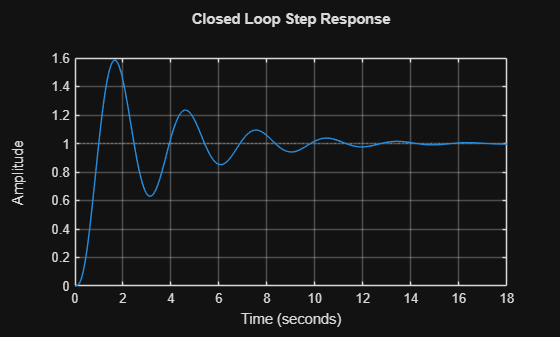


% Closed loop response
sys_cl = feedback(k*sys,1);

figure
step(sys_cl)
title('Closed Loop Step Response')
grid on